plecs

   USAGE: PLECS('CMD','PARAMETER1','PARAMETER2',...)
     Known commands are: get, set, version, hostid, thermal, scope, checkout


open_system('Environment.slx')

## Sistema

fc = 4e3; %[Hz] Carrier frequency
fs = 2 * fc %[Hz] Sampling frecuency = Nyquist Frequency

fs = 8000

Ts = 1 / fs %[s] Sampling period

Ts = 1.2500e-04


Tf = 200*Ts; % [s] Simulation time

Vdc = 100;
Ldc = 1e-3; %[H]
Rdc = 1e-3; %[Ohm]
L = 20e-3; %[H]
R = 1; %[Ohm]

i_max = 100; %[A]

## Create the Environment

Observation space

obsInfo = rlNumericSpec([3, 1],...
    LowerLimit=[-inf -inf 0  ]',...
    UpperLimit=[ inf  inf inf]');

obsInfo.Name = "Observations";
obsInfo.Description = "integrated error, error, and measured current";

Action space

actInfo = rlNumericSpec([1, 1]);
actInfo.Name = "Actions";
actInfo.Description = "d";

Environment creation

env = rlSimulinkEnv("Environment", "Environment/Agent", obsInfo, actInfo);

Reset function (randomizes the reference values during training).

env.ResetFcn = @(in)localResetFcn(in);

Random generator seed

rng(0)

## Critic

DDPG agents use a parametrized Q-value function approximator to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter).

To model the parametrized Q-value function within the critic, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value).

Define each network path as an array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel. Obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

% Observation path
obsPath = [
    featureInputLayer(obsInfo.Dimension(1),Name="obsInLyr")
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(25,Name="obsPathOutLyr")
    ];

% Action path
actPath = [
    featureInputLayer(actInfo.Dimension(1),Name="actInLyr")
    fullyConnectedLayer(25,Name="actPathOutLyr")
    ];

% Common path
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="QValue")
    ];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,obsPath);
criticNetwork = addLayers(criticNetwork,actPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork, ...
    "obsPathOutLyr","add/in1");
criticNetwork = connectLayers(criticNetwork, ...
    "actPathOutLyr","add/in2");

View the critic network configuration.

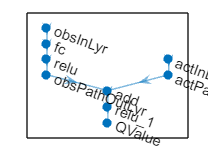

figure
plot(criticNetwork)

Convert the network to a `dlnetwork` object and summarize its properties.

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 1.5k

   Inputs:
      1   'obsInLyr'   3 features
      2   'actInLyr'   1 features



Create the critic approximator object using the specified deep neural network, the environment specification objects, and the names if the network inputs to be associated with the observation and action channels. 

critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsInLyr", ...
    ActionInputNames="actInLyr");

Critic checking

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
-0.1631

## Create the Actor

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor.

A continuous deterministic actor implements a parametrized deterministic policy for a continuous action space. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation.

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer (which returns the action to the environment action channel, as specified by `actInfo`).

Define the network as an array of layer objects.

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(3)
    fullyConnectedLayer(actInfo.Dimension(1))
    sigmoidLayer()
    ];

Convert actor network to dlnetwork object

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 16

   Inputs:
      1   'input'   3 features



Visualize actor network

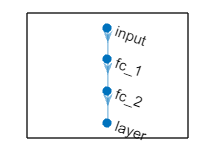

figure
plot(actorNetwork)

Actor object creation

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

Actor checking

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.3552]}


## Create the DDPG Agent

Agent creation

agent = rlDDPGAgent(actor, critic);

Agent options

agent.SampleTime = Ts;

agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 1.0; % gamma
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.ExperienceBufferLength = 1e6; 

agent.AgentOptions.NoiseOptions.Variance = 0.3;
agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

Agent checking

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.2942]}


## Training

Training options

trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=800);

Training

doTraining = true;
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load("DDPG.mat","agent")
end

## Local Reset Function

function in = localResetFcn(in)

% Randomize reference signal
blk = sprintf("Environment/i_ref");
i_ref = 3*randn + 10;
in = setBlockParameter(in, blk, Value=num2str(i_ref));
end


% % Randomize initial current
% i = 3*rand + 10;
% while h <= 0 || h >= 20
%     h = 3*randn + 10;
% end
% blk = "rlwatertank/Water-Tank System/H";
% in = setBlockParameter(in,blk,InitialCondition=num2str(h));